% Section 1. UI default
% HOME - Layout - Default

% Left : Current folder: make sure you can see all of the needed files can
% be visible there

% middle: editor & Command Window

% Live Script(.mlx): This is very useful: can be run immediately:
% list of needed knowledge:
% a. semicolon: print or not
% b. section break
% c. run all/ run section

% Script(.m): defining functions. Can also be used like normal
% programming languages, run by Command window

% Command Window: "The calculator mode": the interactive mode, but useless

% Right: workspace
% you will see defined variables there(after you run it)
% double-click can see their detailed values

disp("make sure you read all above");% disp: short for display

make sure you read all above


% Section 2. Programming Basics:

% rule No.1: always save your file: ctrl+s
% rule No.2: save your file immediately after you create it
% rule No.3: Give everything a good name, so you can remember: your files,
% your functions, your variables: so your work would more likely be
% readable.
% rule No.4: Write comments: if you need it
% rule No.5: make sure the change you make is recoverable: if you decide to
% change your work, make a copy, or other version control tools. When you
% know your attempt is not working, you can go back to the place you
% started.

disp("They are important");% disp: short for display

% Section 3 - the Calculator part
% Now let us learn some actaul programming skills
% Example 1: 
% A linear elastic spring with original length l0, stiffness k
% assume l0 is 20, k is 5
% 1. current length l is 15, what is the force?
l0 = 20;
k = 5;
l = 15;
force = k*(l-l0)

force = -25


%2. what is the elastic energy?
E = 0.5*k*(l-l0)^2

E = 62.5000


% the example above is quite easy to understand, you just define the value
% of your variable and then calculate the results with the equations. 


% Now we want to calculate a mass spring motion
% Step 1: define our problem
% We want to find out how would a mass-spring system behave in a short
% period
% Step 2: define our problem mathematically
% We want to know the how would the position and velocity of the mass
% changes over time--same as find out X and V with functions: 
% F = m*(dv/dt); F = m*(d2x/dt2)
% Step 3: what method are we using?
% we are trying to simulate the system for short period of time and find
% for each time step t, the system poistion X and velocity V
% Step 4: what equations are we using?
% The system of SHM has been solved. 
% We know X = Amplitude*cos(wt) 
% And we use the equation of angular frequency 
% w = sqrt(k/m)
% let us just assume the max displacement is 5, so A = 5

t = 0;
A = 5;
k = 5;
m = 0.2;
w = sqrt(k/m)

w = 5

x = A*cos(w*t)

x = 5


% but we need to plot X vs t
% the method is the simple: we sample the function discretely and connect
% the dots
% so we need to define a sequence of time
step = 0.1;
endtime = 10; % start time is zero no need to define
T = 0:step:endtime

T =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


% you can write 0:0.1:30, this would be hard to change the experiements in
% the future

X = A*cos(w*T)

X =     5.0000    4.3879    2.7015    0.3537   -2.0807   -4.0057   -4.9500   -4.6823   -3.2682   -1.0540    1.4183    3.5433    4.8009    4.8829    3.7695    1.7332   -0.7275   -3.0101   -4.5557   -4.9859   -4.1954   -2.3777    0.0221    2.4165    4.2193    4.9890    4.5372    2.9746    0.6837   -1.7746   -3.7984   -4.8923   -4.7883   -3.5120   -1.3758    1.0972    3.3016    4.6976    4.9435    3.9791    2.0404   -0.3978   -2.7386   -4.4090   -4.9998   -4.3665   -2.6642   -0.3095    2.1209    4.0320


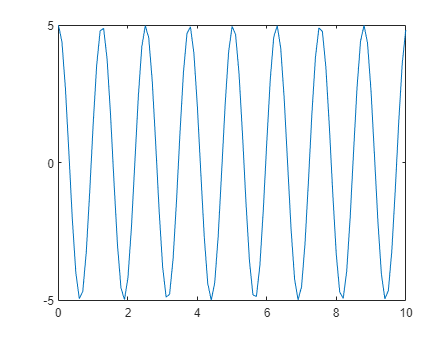

% lastly: we plot it
plot(T,X)


% this discontinuety is quite obvious, try with small step size


% Section 4: the programming part(optional):
% 4.1 Function call

% 4.2 Element-wise operator